# 遗传算法学习

根据目标函数计算函数最小值

clear;clc;close all;

构造目标函数

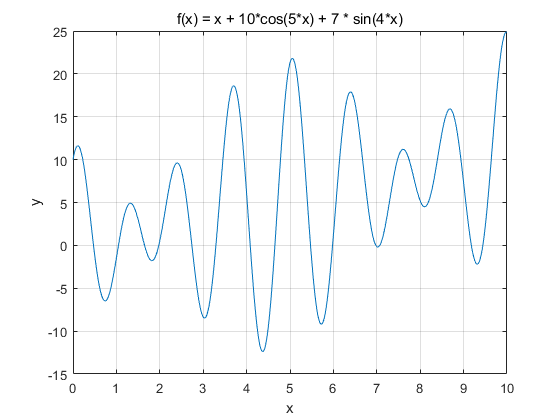

func = @(x)x + 10*cos(5*x) + 7 * sin(4*x);

x = 0:0.01:10;
plot(x,func(x));grid on;xlabel('x');ylabel('y');title("f(x) = x + 10*cos(5*x) + 7 * sin(4*x)")

参数设置

NP = 50;                                                                    %种群规模
L  = 20;                                                                    %二进制串长度
Pc = 0.8;                                                                   %交叉率
Pm = 0.05;                                                                  %变异率
G  = 100;                                                                   %最大遗传代数
Xs = 10;                                                                    %上限
Xx = 0;                                                                     %下限


group_bin  = randi([0 1],NP,L);                                             %随机获得初始二进制种群
group_dec = Xx+(Xs-Xx)*bin2dec(num2str(group_bin))./(2^L-1);                %缩放到数值范围区域后的初始种群

Fit = func(group_dec);                                                      %各个种群参数落在函数上的值

max_fit = max(Fit);
min_fit = min(Fit);

rr = find(Fit == min_fit);                                                  %种群中最优个体
rr,group_dec(rr),func(group_dec(rr))                                        %个体编号，个体值，函数值

rr =     17


ans =           4.34401926423956


ans =           -12.257756415184


group_bin(rr,:)                                                             %最佳个体二进制数值

ans =      0     1     1     0     1     1     1     1     0     0     1     1     0     1     0     0     1     1     1     1


group_dec(rr,:)                                                             %最佳个体十进制数值

ans =           4.34401926423956
